# Project: Radar Target Generation and Detection

## Project Overview

The main aim of this project is to practically apply and demonstrate various radar signal techniques learned during the course. The ultimate goal is to successfully detect a target using the 2D-Constant False Alarm Rate (CFAR) technique.

The project layout is shown below.

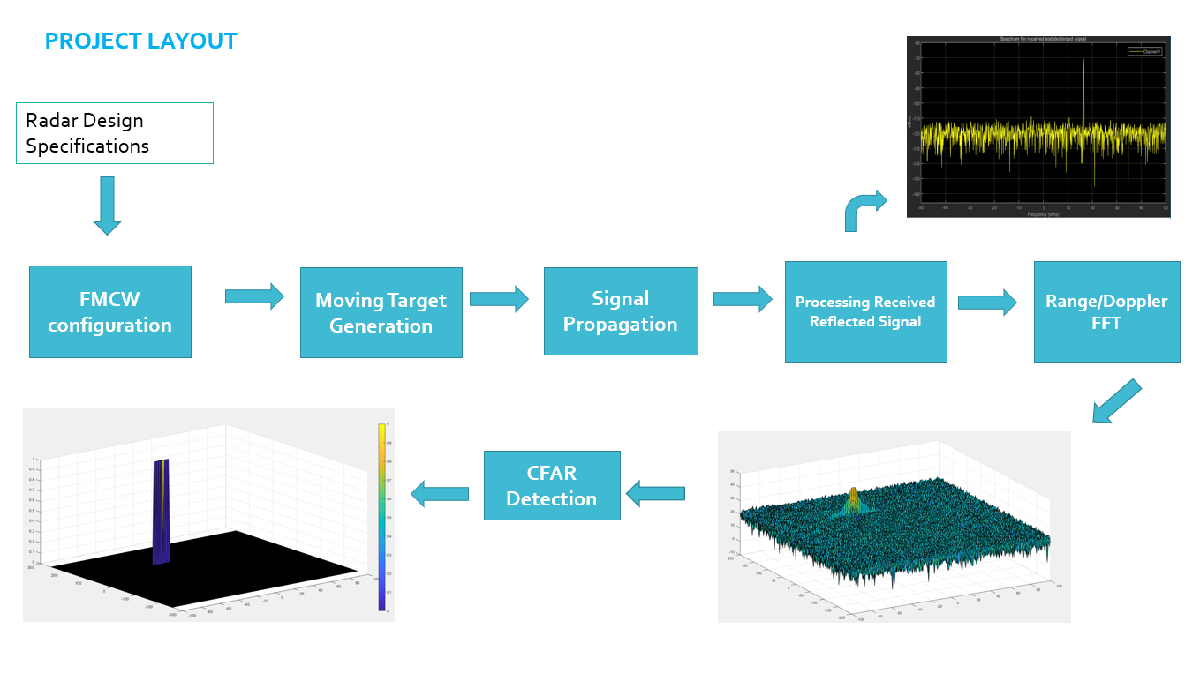

Here's a step-by-step breakdown of this exciting radar mission:

- Setting up the FMCW Waveform: We'll start by configuring the Frequency Modulated Continuous Wave (FMCW) waveform to meet system requirements.

- Defining Target Range and Velocity: With a solid grasp of radar principles, we'll precisely define the range and speed of the target, simulating its movement in a virtual environment.

- Processing Transmit and Receive Signals: In the same simulation loop, we'll process the signals sent and received to determine the beat signal.

- Determining Range with FFT: We'll perform a Range Fast Fourier Transform (FFT) on the received signal to figure out the range of detected targets.

- Enhancing Precision with CFAR Processing: As we approach the project's peak, we'll use the 2D Constant False Alarm Rate (CFAR) technique on the second FFT's output to pinpoint the target with precision.

clear all
clc;

## Radar Specifications

### FMCW RADAR

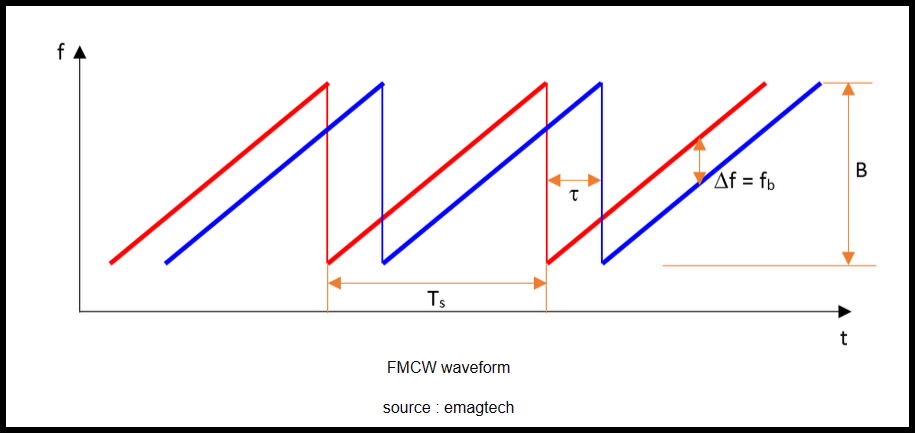

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency of operation = 77GHz
% Max Range = 200m
Rmax = 200;
% Range Resolution = 1 m
rangeRes = 1;
% Max Velocity = 100 m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%speed of light = 3e8
c = 3e8;

### FMCW Waveform Generation


$$\textrm{Bandwidth}:\;\;B=\frac{\textrm{speed}\;\textrm{of}\;\textrm{light}\;\left(c\right)}{2*\textrm{range}\;\textrm{resolution}}$$


${\textrm{Chirp}\;\textrm{Time}:\;T}_{\textrm{chirp}} \;\left(\textrm{or}\;T_s \right)=\frac{5\ldotp 5*2*R_{\max } }{\textrm{speed}\;\textrm{of}\;\textrm{light}\;\left(c\right)}$  In general, for an FMCW radar system, the sweep time should be at least 5 to 6 times the round trip time


$$\textrm{Slope}=\frac{B}{T_{\textrm{chirp}} }$$


%Design the FMCW waveform by giving the specs of each of its parameters.
% Calculate the Bandwidth (B), Chirp Time (Tchirp) and Slope (slope) of the
% FMCW chirp using the requirements above.
B = c/(2*rangeRes);
disp(B);
Tchirp = 5.5*2*Rmax/c;
disp(Tchirp);
slope = B/Tchirp;
disp(slope);
%Operating carrier frequency of Radar
fc= 77e9;             %carrier freq

%The number of chirps in one sequence. Its ideal to have 2^ value for the
%ease of running the FFT for Doppler Estimation.
Nd=128;                   % #of doppler cells OR #of sent periods % number of chirps

%The number of samples on each chirp.
Nr=1024;                  %for length of time OR # of range cells

% Timestamp for running the displacement scenario for every sample on each
% chirp
t=linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples


%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx=zeros(1,length(t)); %transmitted signal
Rx=zeros(1,length(t)); %received signal
Mix = zeros(1,length(t)); %beat signal

%Similar vectors for range_covered and time delay.
r_t=zeros(1,length(t));
td=zeros(1,length(t));

## Signal Generation and Moving Target simulation

Running the radar scenario over the time. 

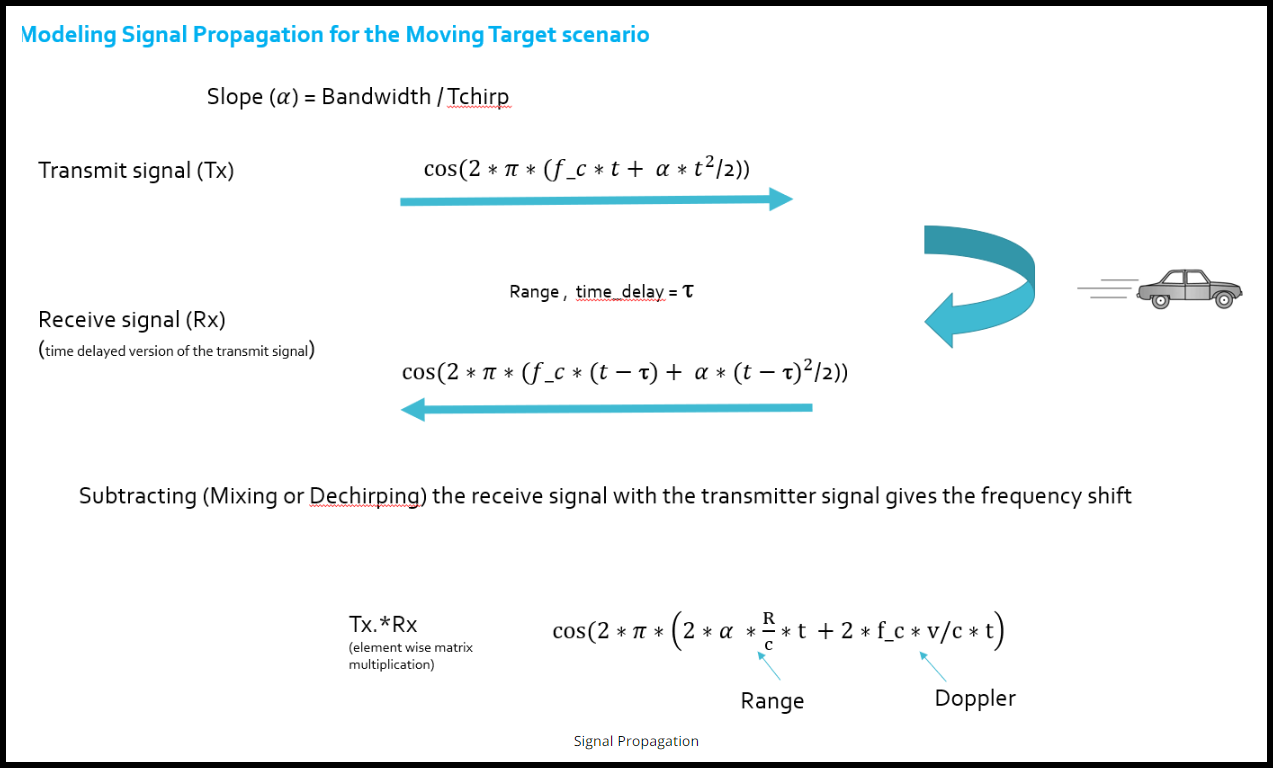

### User Defined Range and Velocity of target

Define the target's initial position and velocity. Note : Velocity remains contant

Range cannot exceed the max value of 200m and velocity can be any value in the range of -70 to + 70 m/s.

 % Target's initial position (m)
 x_init = 100; 
 % Targets intial (relative) velocity (m/s)
 v_init = 30;

 deltaT = t(2) - t(1);
 x_prev = 0.0;
 for i=1:length(t)

     %For each time stamp update the Range of the Target for constant
     %velocity.
     if i == 1
         x = x_init;
         v = v_init;
     else
         x = x_prev + v*deltaT;
     end

     %For each time sample we need to update the transmitted and received
     %signal.
     Tx(i) = cos(2*pi*( (fc*t(i)) + ((slope*t(i)^2)/2)) );
     % delay time = time taken for signal to hit target and come back
     tau = (2*x)/(c);
     Rx(i)  = cos(2*pi*(( fc * (t(i) - tau)) + (( slope * (t(i) - tau)^2 )/2 )));

     %Now by mixing the Transmit and Receive generate the beat signal This
     %is done by element wise matrix multiplication of Transmit and
     %Receiver Signal.
     % By implementing the 2D FFT on this beat signal, we
     %can extract both Range and Doppler information
     Mix(i) = Tx(i).*Rx(i);

     x_prev = x;

 end

## RANGE MEASUREMENT

### Range Estimation Equation

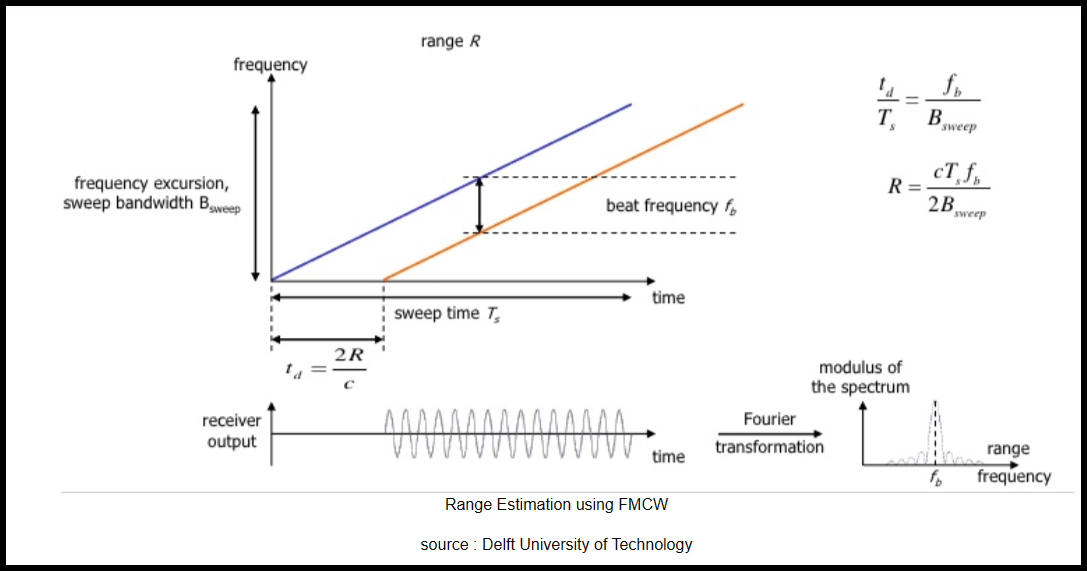

It is important to understand that if a target is stationary then a transmitted frequency and received frequency are the same. But, the ramping frequency within the hardware is continuously changing with time. So, when we take the delta (beat frequency) between the received and ramping frequency we get the trip time.

### FFT and FMCW

Fast Fourier Transform is used to convert the signal from time domain to frequency domain. Conversion to frequency domain is important to do the spectral analysis of the signal and determine the shifts in frequency due to range and doppler.

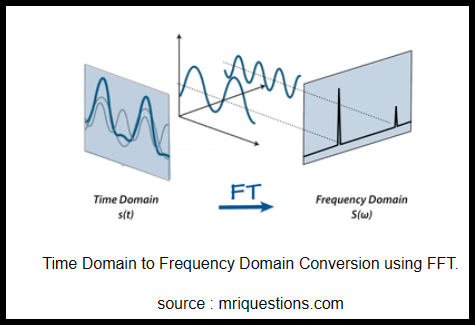

As seen in the image below, the Range FFTs are run for every sample on each chirp. Since each chirp is sampled Nr times, it will generate a range FFT block of Nr * (Number of chirps). These FFT blocks are also called FFT bins.

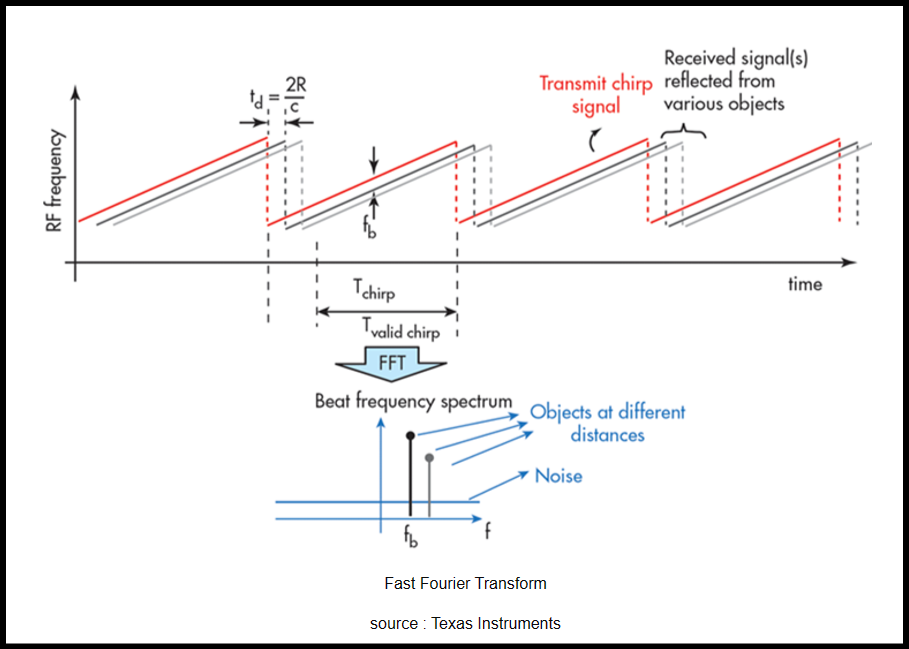

Each bin in every column of the block represents an increasing range value so that the end of the last bin represents the maximum range of a radar.

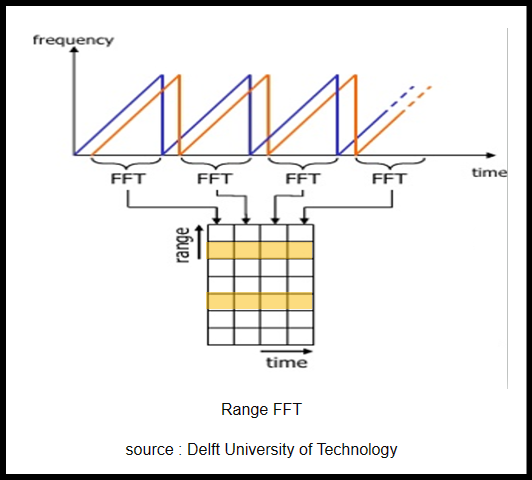

 % Reshape the vector into Nr*Nd array. Nr and Nd here would also define the
 % size of
 %Range and Doppler FFT respectively.
Mix= reshape(Mix,[Nr,Nd]);

% Run the FFT on the beat signal along the range bins dimension (Nr) and
%normalize.
% Take the absolute value of FFT output
signal_fft = fft(Mix,[],1);
P2 = abs(signal_fft/Nr);

% Output of FFT is double sided signal, but we are interested in only one
% side of the spectrum. Hence we throw out half of the samples.
P1  = P2(1:Nr/2,2);

% Plotting the range
figure ('Name','Range from First FFT')
% Plot FFT output
range = reshape((0:(Nr/2)-1),size(P1));
plot(range,P1)
title('Single-Sided Amplitude Spectrum of Range')
xlabel('Range (m)')
ylabel('|P1|')

axis ([0 200 0 0.4]);

## RANGE DOPPLER RESPONSE

The 2D FFT implementation is already provided here. This will run a 2DFFT on the mixed signal (beat signal) output and generate a range doppler map.

### FMCW Doppler Measurements

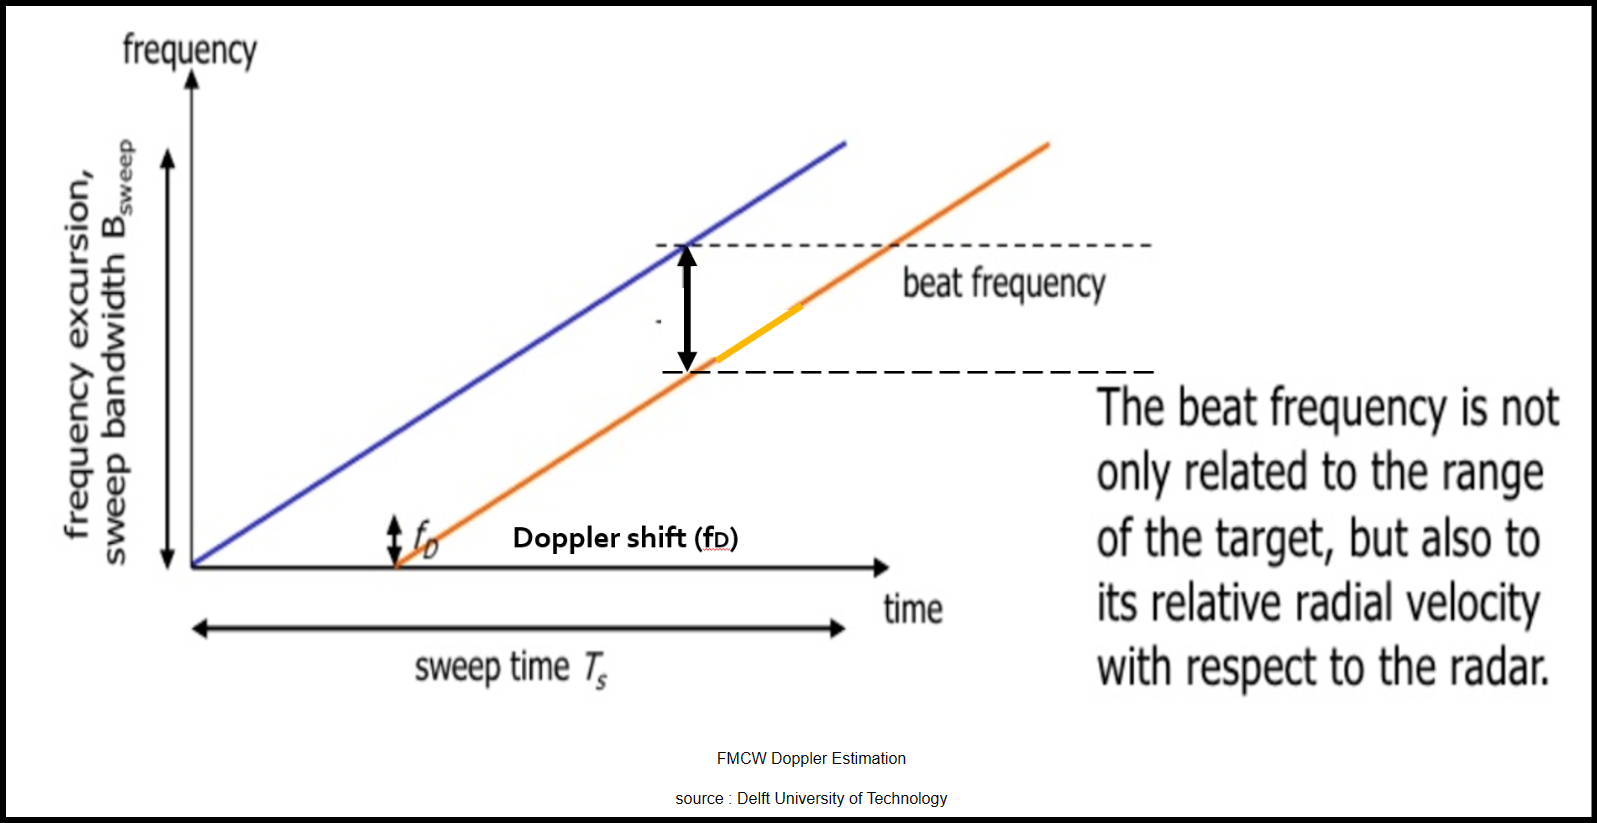

 There will be a shift in the received signal frequency due to the doppler effect of the target’s velocity. The doppler shift is directly proportional to the velocity of the target as shown below.

$f_D =\frac{2v_r }{\lambda }$��

- $f_D$�: shift in the transmitted frequency due to the doppler

- $v_r$: relative velocity of the target

- $\lambda$ : wavelength of the signal

By measuring the shift in the frequency due to doppler, radar can determine the velocity. The receding target will have a negative velocity due to the frequency dropping lower, whereas the approaching target will have positive velocity as the frequency shifts higher.

The beat frequency comprises of both frequency components: $f_r$� (frequency delta due to range) and $f_d$ (frequency shift due to velocity).** Although, in the case of automotive radar the  **$f_d$**� is very small in comparison to the **$f_r$**��. Hence, the doppler velocity is calculated by measuring the rate of change of phase across multiple chirps (**$\left.N_d \right)$**.** The following equation shows the relationship between the rate of change of the phase $\phi$, and the frequency:


$$\frac{\mathrm{d}}{\mathrm{d}t}\phi =\textrm{frequency}$$


### 2D - FFT

Once the range bins are determined by running range FFT across all the chirps, a second FFT is implemented along the second dimension to determine the doppler frequency shift. As discussed, the doppler is estimated by processing the rate of change of phase across multiple chirps. Hence, the doppler FFT is implemented after all the chirps in the segment are sent and range FFTs are run on them.

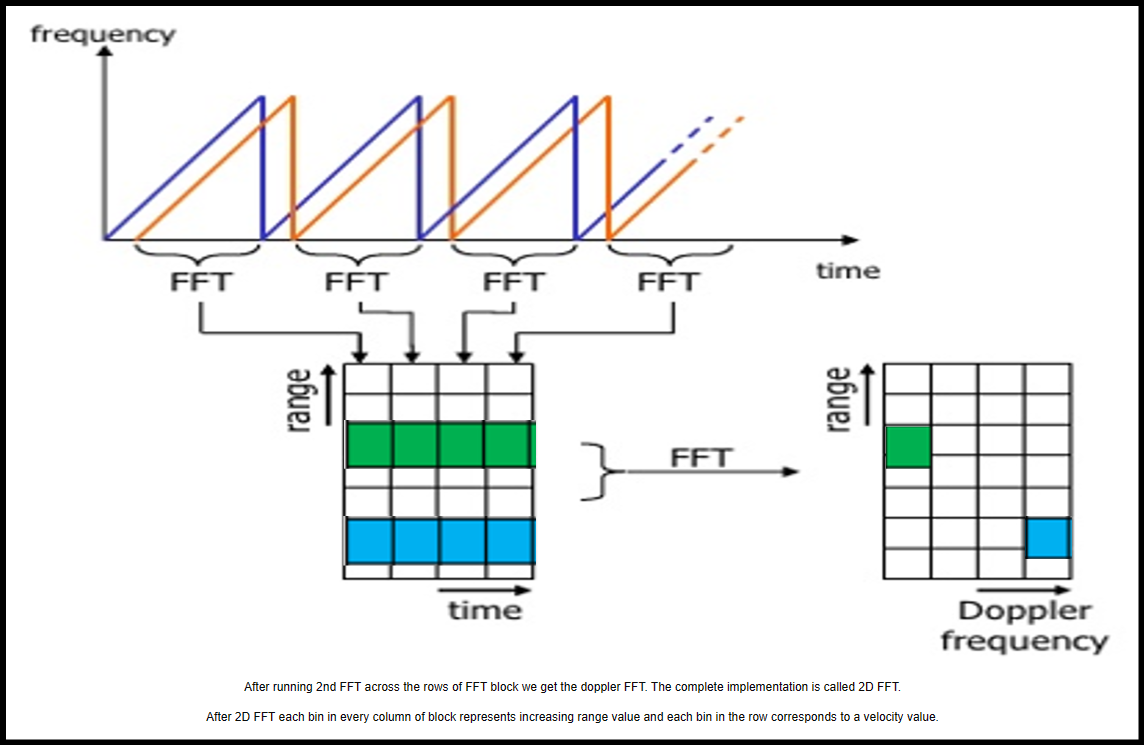

The output of the first FFT gives the beat frequency, amplitude, and phase for each target. This phase varies as we move from one chirp to another (one bin to another on each row) due to the target’s small displacements. Once the second FFT is implemented it determines the rate of change of phase, which is nothing but the doppler frequency shift.

### Range Doppler Map (RDM)

The output of Range Doppler response represents an image with Range on one axis and Doppler on the other. This image is called as Range Doppler Map (RDM). These maps are often used as user interface to understand the perception of the targets.

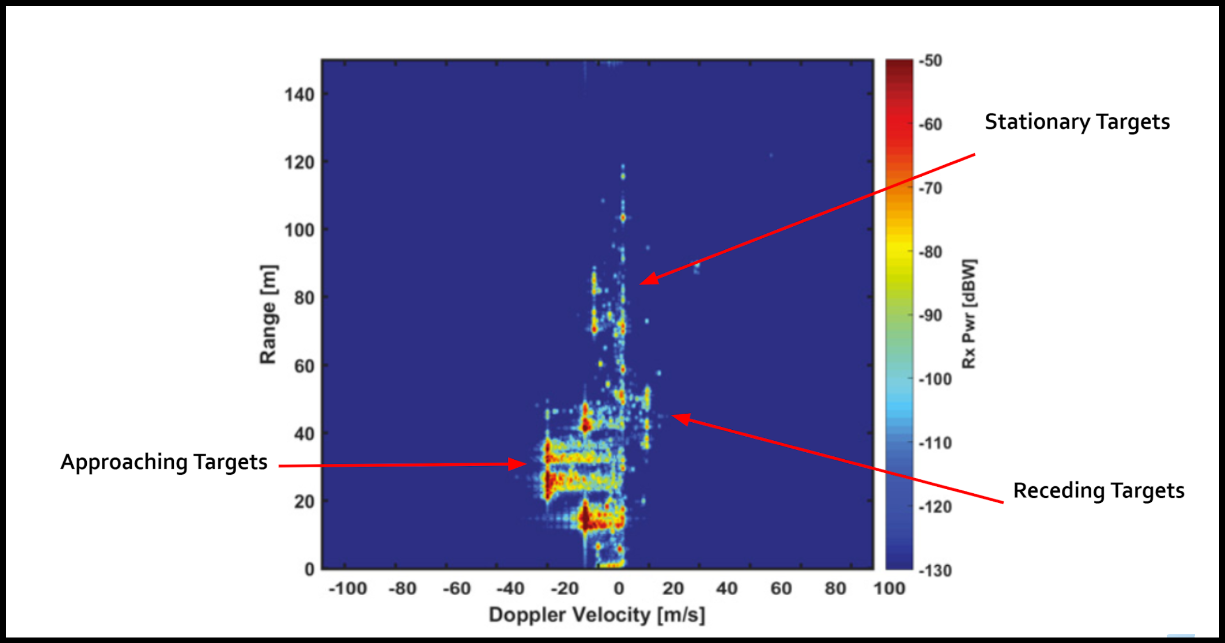

% Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
%Shift zero-frequency terms to the center of the array
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);

## 2D-CFAR implementation

### CFAR Introduction

Radar not only receive the reflected signals from the objects of interest, but also from the environment and unwanted objects. The backscatter from these unwanted sources is called as clutter.

These unwanted signals are generally produced by the reflections from the ground, sea, buildings, trees, rain, fog etc. 

It is important to filter out clutter for successful detection of targets. **This is critical in a driving scenario to avoid the car from suddenly braking in the absence of valid targets.** This sudden braking happens when the radar detects reflections that are generated from the clutter.

One technique to filter out cluttering is *fixed clutter thresholding*. With fixed thresholding, signal below the threshold value is rejected. With this method, if the detection threshold is set too high, there will be very few false alarms, but it will also mask the valid targets. If the threshold is set too low, then it would lead to too many false alarms. In other words, the *false alarm rate* would be too high.

The false alarm rate is the rate of erroneous radar detections by noise or other interfering signals. It is a measure of the presence of detected radar targets when there is no valid target present.

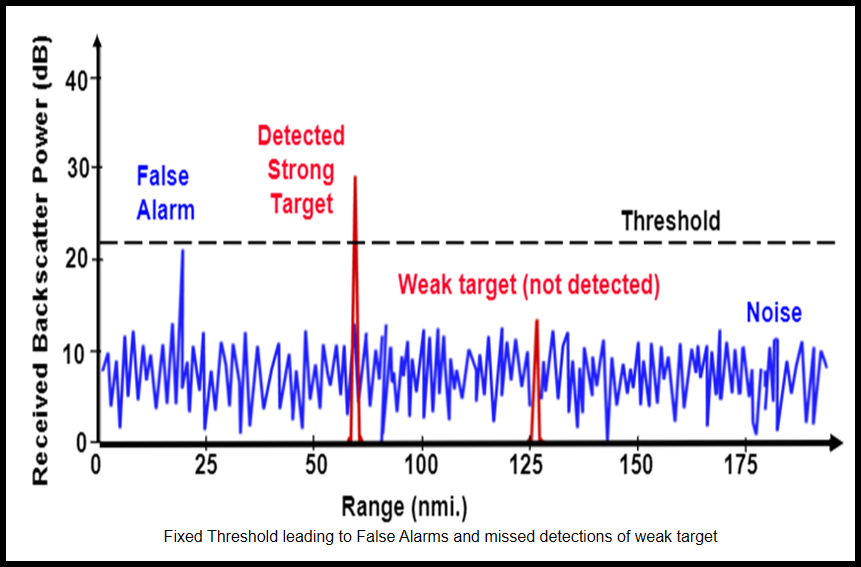

Another approach to clutter thresholding is to use *dynamic thresholding*. Dynamic thresholding involves varying the threshold level to reduce the false alarm rate.

CFAR (Constant False Alarm Rate) is one such dynamic thresholding technique. With this technique, the noise at every or group of range/doppler bins is monitored and the signal is compared to the local noise level. This comparison is used create a threshold which holds the false alarm rate constant.

### CA-CFAR

CA-CFAR is the most commonly used CFAR detection technique. As seen in the previous sections, the FFT blocks are generated on implementing range and doppler FFTs across the number of chirps. The CFAR process includes the sliding of a window across the cells in FFT blocks. Each window consists of the following cells.

**Cell Under Test** : The cell that is tested to detect the presence of the target by comparing the signal level against the noise estimate (threshold).

**Training Cells** : The level of noise is measured over the Training Cells. The Training Cells can be divided into two regions, the cells lagging the CUT, called lagging Training Cells and the cells leading the CUT, called Leading Training Cells. The noise is estimated by averaging the noise under the training cells. In some cases either leading or lagging cell average is taken, while in the other the leading and lagging cell average is combined and the higher of two is considered for noise level estimate.

The number of training cells should be decided based on the environment. If a dense traffic scenario then the fewer training cells should be used, as closely spaced targets can impact the noise estimate.

**Guard Cells** : The cells just next to CUT are assigned as Guard Cells. The purpose of the Guard Cells is to avoid the target signal from leaking into the training cells that could adversely affect the noise estimate. The number of guard cells should be decided based on the leakage of the target signal out of the cell under test. If target reflections are strong they often get into surrounding bins.

**Threshold Factor (Offset)** : Use an offset value to scale the noise threshold. If the signal strength is defined in logarithmic form then add this offset value to the average noise estimate, else multiply it

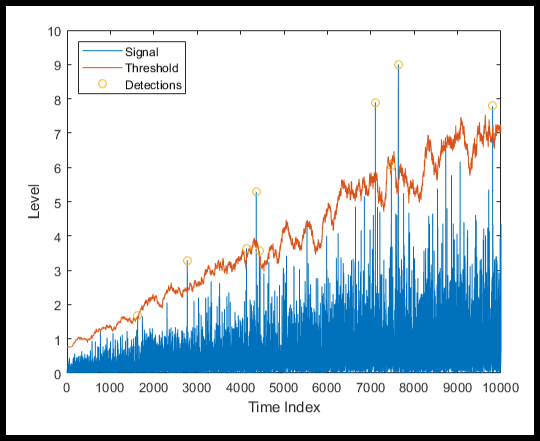

### 2D-CFAR Technique

The 2D CFAR is similar to 1D CFAR, but is implemented in both dimensions of the range doppler block. The 2D CA-CFAR implementation involves the training cells occupying the cells surrounding the cell under test with a guard grid in between to prevent the impact of a target signal on the noise estimate.

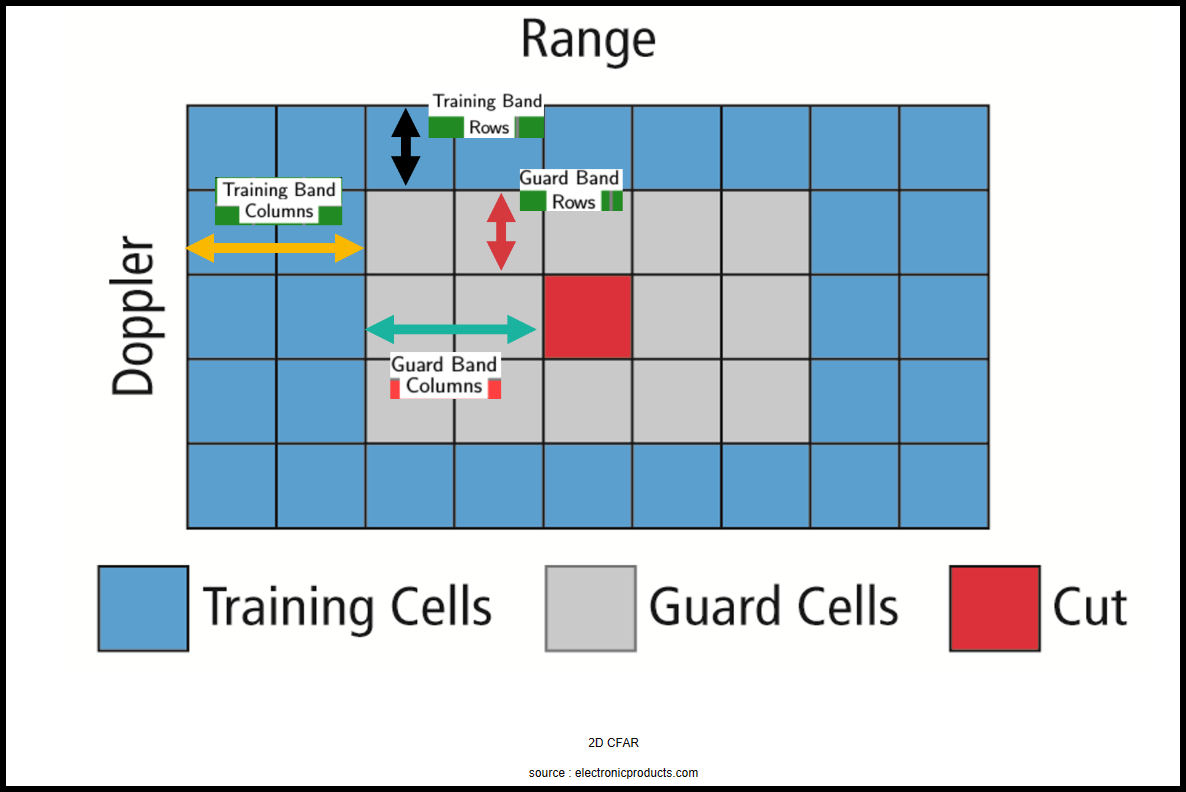

#### Selection of Training and Gaurd Cells

If we see the RDM Map, we can observe that the spread of the signal values is more across the doppler (or velocity) axis than compared to the range axis.

Keeping this in mind, the number of gaurd and training cells required for doppler axis will be also more than the range cells to capture the average noise better.

%Select the number of Training Cells in both the dimensions.
Tr = 20; % Training cells across range axis
Td = 40; % Training cells across doppler axis

% *%TODO* :
%Select the number of Guard Cells in both dimensions around the Cell under
%test (CUT) for accurate estimation
Gr = 10; % Gaurd cells across range axis
Gd = 20; % Gaurd cells across doppler axis

% Total number of training cells
noOfTrainingCells =  ((2*Tr+2*Gr+1)*(2*Td+2*Gd+1)) - ((2*Gr+1)*(2*Gd+1));


### **Selection of offset**

Below is the RDM map seen from the doppler and range axis.

The average noise level is ~25 dbm and the peak signal is ~40 dbm. So the offset is selected as somewhere around 15 dBm above the average noise to provide good SNR.

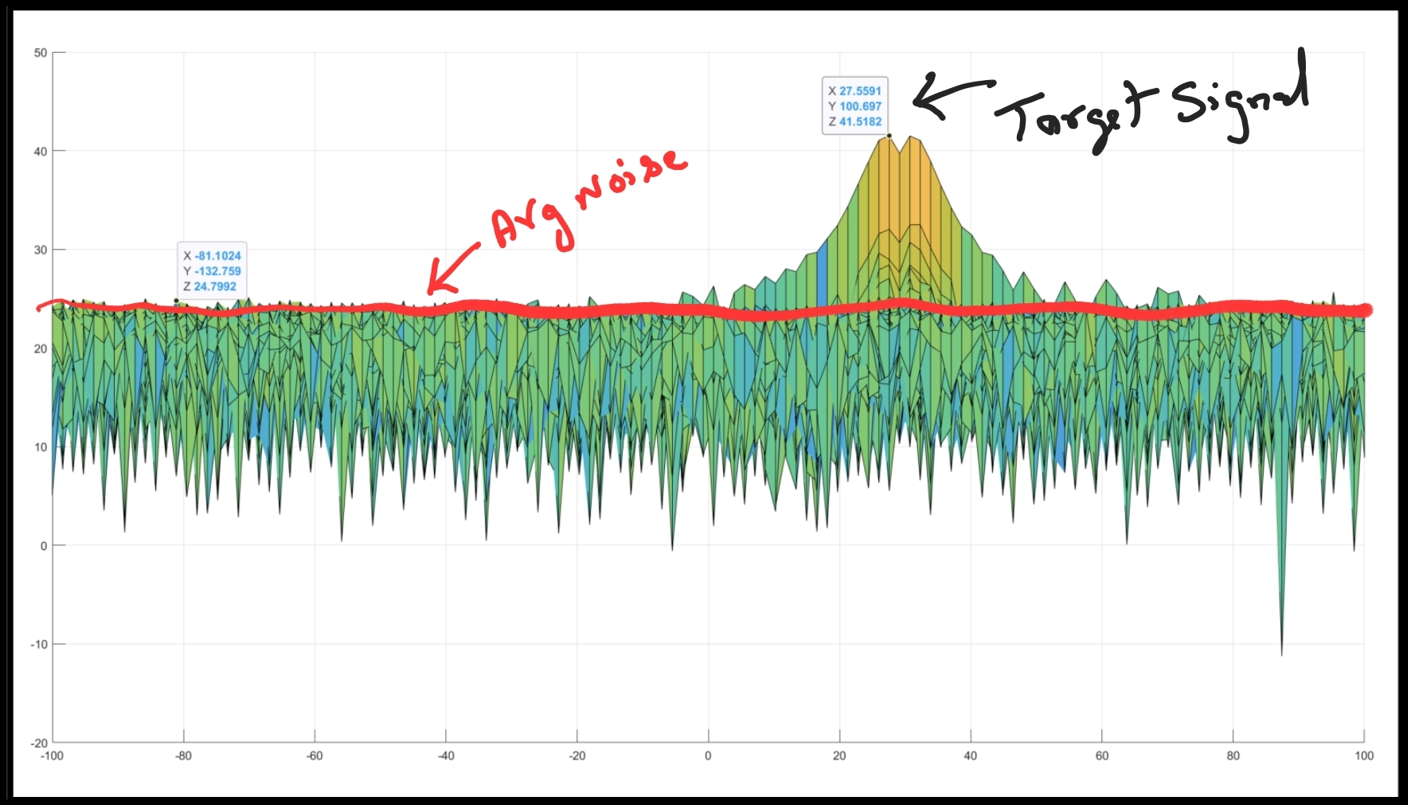  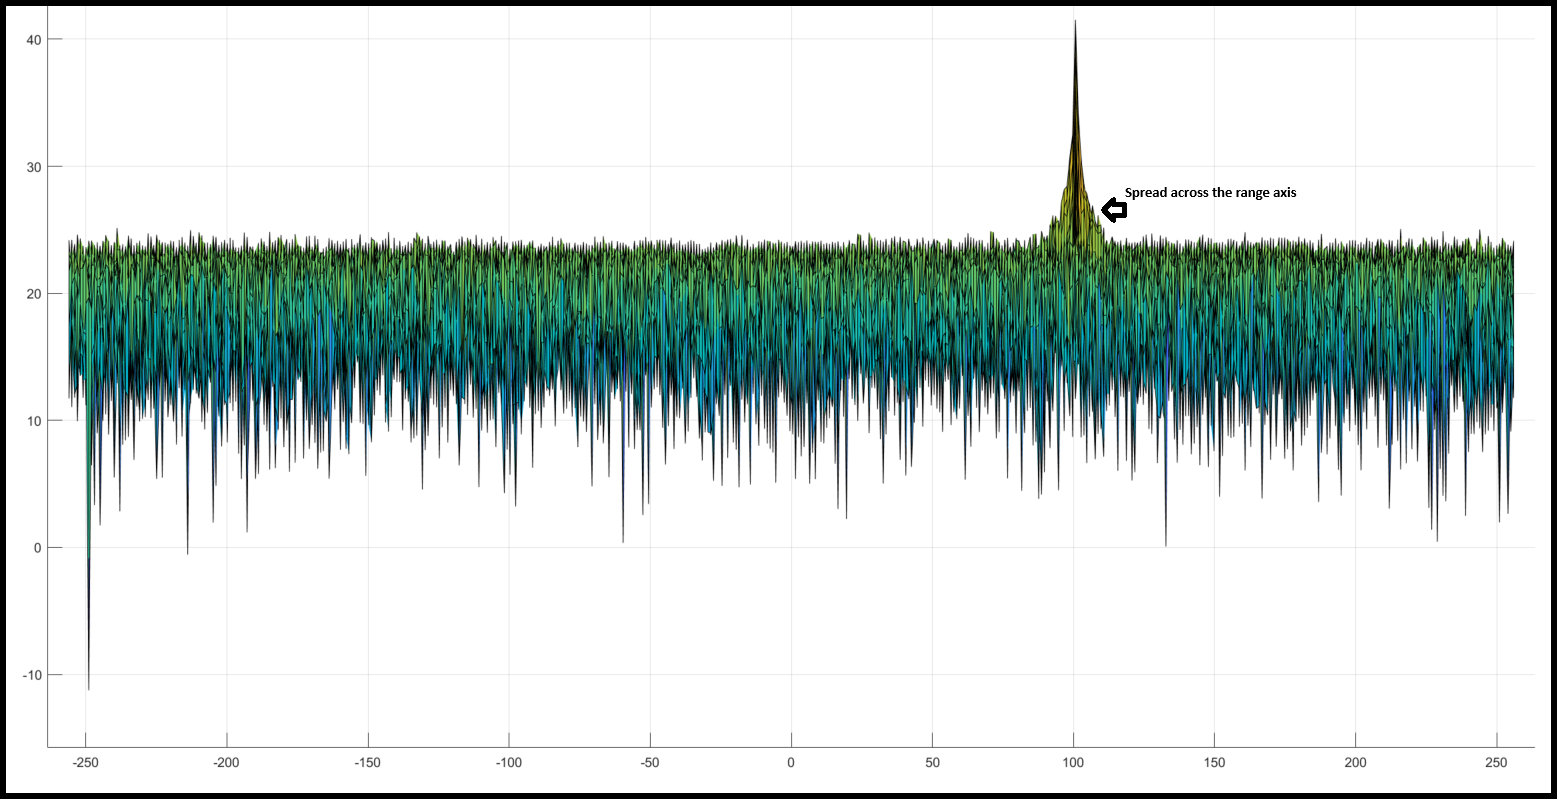

% Offset the threshold by SNR value in dB
offset = 10;

%Create a vector to store noise_level for each iteration on training cells
noise_level = zeros(1,1);

### Implementation of 2D-CFAR

The following steps are used to implement 2D-CFAR:

- Go through each CUT (making sure the edges are excluded on all sides) and loop through the whole RDM matrix

- Extract the grid that includes the training, guard and CUT cells. Grid Size = (2Tr+2Gr+1)(2Td+2Gd+1).

- Convert all values from dB to power(mW) units

- The total number of cells in the guard region and cell under test. (2Gr+1)(2Gd+1).

- Suppress (=0.0) the values in guard cells and CUT cell

- Now only the training cells have non-zero values. This gives the Training Cells : (2Tr+2Gr+1)(2Td+2Gd+1) - (2Gr+1)(2Gd+1)

- Sum and average the noise across all the training cells. This gives the threshold

- Convert the noise level to dBm

- Add the offset to the threshold to keep the false alarm to the minimum.

- Determine the signal level at the Cell Under Test.

- If the CUT signal level is greater than the Threshold, assign a value of 1, else equate it to zero.

- Since the cell under test are not located at the edges, due to the training cells occupying the edges, we suppress the edges to zero. Any cell value that is neither 1 nor a 0, assign it a zero.

% Final output map with threshold (Initialized to zero and later only the
% thresholded cells will be filled with value in later steps)
RDM_wCFAR = zeros(size(RDM));
% Matrix of noise levels at each cell
RDM_NoiseLevel = zeros(size(RDM));
% Get the size of RDM map
[noofRows, noofCols] = size(RDM);

% Go through each CUT (making sure the edges are excluded on all sides) and
% loop through the whole RDM matrix
for x = (Td+Gd+1) : (noofRows - (Td+Gd+1)) % loop across all rows excluding edges
    for y = (Tr+Gr+1) :(noofCols - (Tr+Gr+1)) % loop across all cols excluding edges

        %disp([x,y]);
        % Extract the grid that containes the CUT cell and its respective
        % guard and training cell that surround it.
        currEvalblock = RDM( ((x-Gd-Td) : (x+Gd+Td)), ((y-Gr-Tr) : (y+Gr+Tr)) );
        % Convert all values from dB to power(mW) units
        currEvalblock = db2pow(currEvalblock);
        % Suppress (=0.0) the guard cells and CUT cell
        currEvalblock( (Td+1) : (2*Td+2*Gd+1-Td), (Tr+1): (2*Tr+2*Gr+1-Tr) ) = 0.0;
        % Now only the training cells have non-zero values. Sum them and
        % take average to get the average noise level for the CUT
        noise_level =  sum(currEvalblock, 'all')/noOfTrainingCells;
        % Convert the noise level to dBm
        noise_level_db = pow2db(noise_level);
        % Add offset to the noise level
        noise_level_db = noise_level_db + offset;
        % Add the noise level to the noise level matrix
        RDM_NoiseLevel(x,y) = noise_level_db;

        % if the current CUT signal strength is > noise then set the output
        % as
        if RDM(x,y) > noise_level_db
            RDM_wCFAR(x,y) = 1.0;
        end

    end % End of loop across RDM columns or range bins
end % End of loop across RDM rows or doppler bins


%Doppler Response output.
%figure,surf(doppler_axis,range_axis,RDM_NoiseLevel);
figure,surf(doppler_axis,range_axis,RDM_wCFAR);
colorbar;

If we look the above graph from top view we can see that the target is located at$100\pm 5$ m in range and the velocity is $30\pm 10$ m/s.

It can be observed for the given filter parameters, the range measurement accuracy is pretty decent but the variation in velocity (doppler) measurement is quite high.

We can further increase the offset to make the threshold higher to improve the SNR but this can have the side effect that the weaker targets may not be detected.